# ROBOTICS: Final Work

*Author: Yeray Navarro Soler*

The main objective of this project is to apply all the acquired knowledge during this Robotics course. It consists on computing the model of a UR5 Robot, as well as the Kinematics, Dynamics and creating a control scheme. Some parts of this proces will be done twice, first with the Symbolic Toolbox, and then with the Robotic Toolbox to verify the results obtained.

## 1. Modelling: Compute the DH parameters

First of all, the link lengths must be defined:

% Link length
L1 = 0.0892;
L2 = 0.1359;
L3 = 0.4250;
L4 = 0.1197;
L5 = 0.3923;
L6 = 0.0930;
L7 = 0.0947;
L8 = 0.0823;

Then, the link frames are defined following the next figure to enable the DH parameter computation. As the UR5 robot has 6 links, there would be 7 frames.

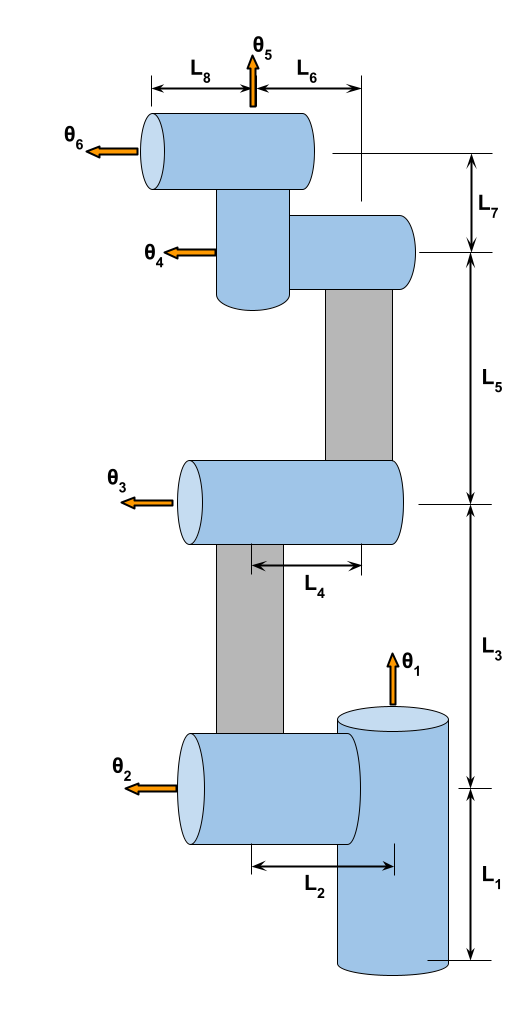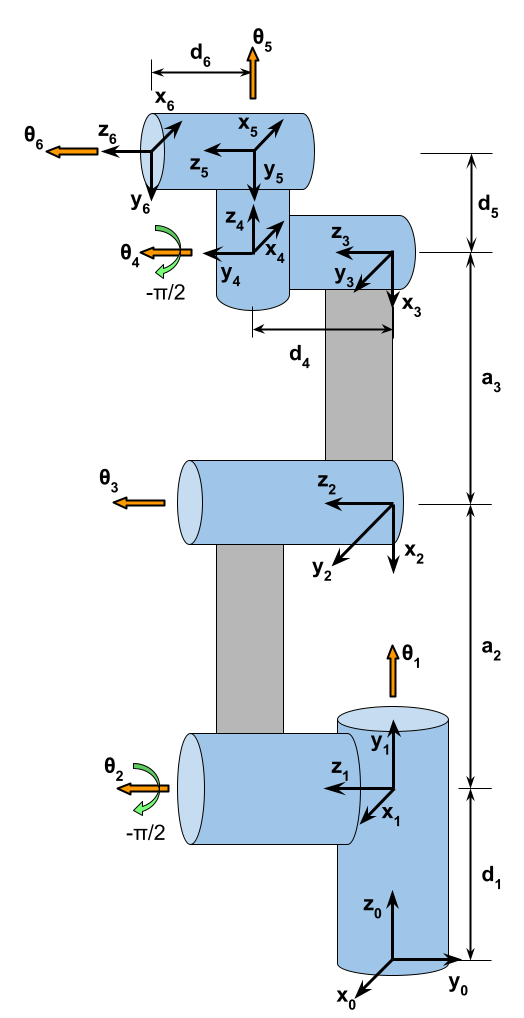

% d
vd1 = L1;
vd2 = 0;
vd3 = 0;
vd4 = L2-L4+L6;
vd5 = L7;
vd6 = L8;

% a
va1 = 0;
va2 = -L3;
va3 = -L5;
va4 = 0;
va5 = 0;
va6 = 0;

% alpha
valpha1 = pi/2;
valpha2 = 0;
valpha3 = 0;
valpha4 = pi/2;
valpha5 = -pi/2;
valpha6 = 0;

% L = Link(theta, d, a, alpha); - DH parameters
L(1) = Link([0  vd1  va1  valpha1]); % L(1) = Link([0        L1   0  pi/2]);
L(2) = Link([0  vd2  va2  valpha2]); % L(2) = Link([0         0 -L3     0]); offset=-pi/2
L(3) = Link([0  vd3  va3  valpha3]); % L(3) = Link([0         0 -L5     0]);
L(4) = Link([0  vd4  va4  valpha4]); % L(4) = Link([0  L2-L4+L6   0  pi/2]); offset=-pi/2
L(5) = Link([0  vd5  va5  valpha5]); % L(5) = Link([0        L7   0 -pi/2]);
L(6) = Link([0  vd6  va6  valpha6]); % L(6) = Link([0        L8   0     0]);

With all the parameters determined, the robot model can be created. The model is created at this point to be able to show a representation of the robot in a particular configuration. Nonetheless, this model will not be used until point *3. Robotic Toolbox*.

UR5 = SerialLink(L, 'name', 'UR5')

 
UR5 = 
 
UR5:: 6 axis, RRRRRR, stdDH, fastRNE                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|     0.0892|          0|     1.5708|          0|
|  2|         q2|          0|     -0.425|          0|          0|
|  3|         q3|          0|    -0.3923|          0|          0|
|  4|         q4|     0.1092|          0|     1.5708|          0|
|  5|         q5|     0.0947|          0|    -1.5708|          0|
|  6|         q6|     0.0823|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


Offsets can be set to put the robot in a particular position. In this case, to observe the home position of this robot at configuration [0,0,0,0,0,0], no offsets must be applied:

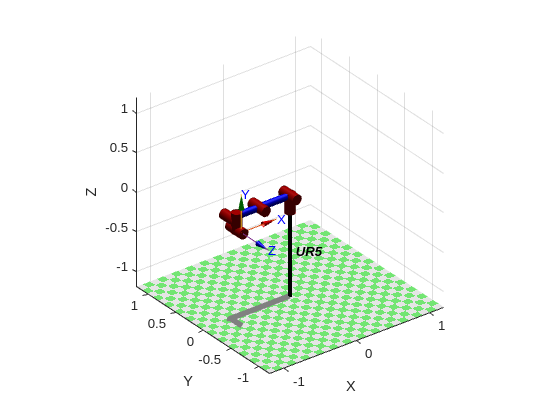

% Plot configuration
UR5.plot([0 0 0 0 0 0])

Furthermore, in this case, to match the configuration shown in the previous figures at configuration [0,0,0,0,0,0], the offsets that must be applied are offset2 = -pi/2 and offset4 = -pi/2. An image of the obtained plot is presented below (due to problems to plot both the prevous and this image at the same time, an image have been used instead of the code).

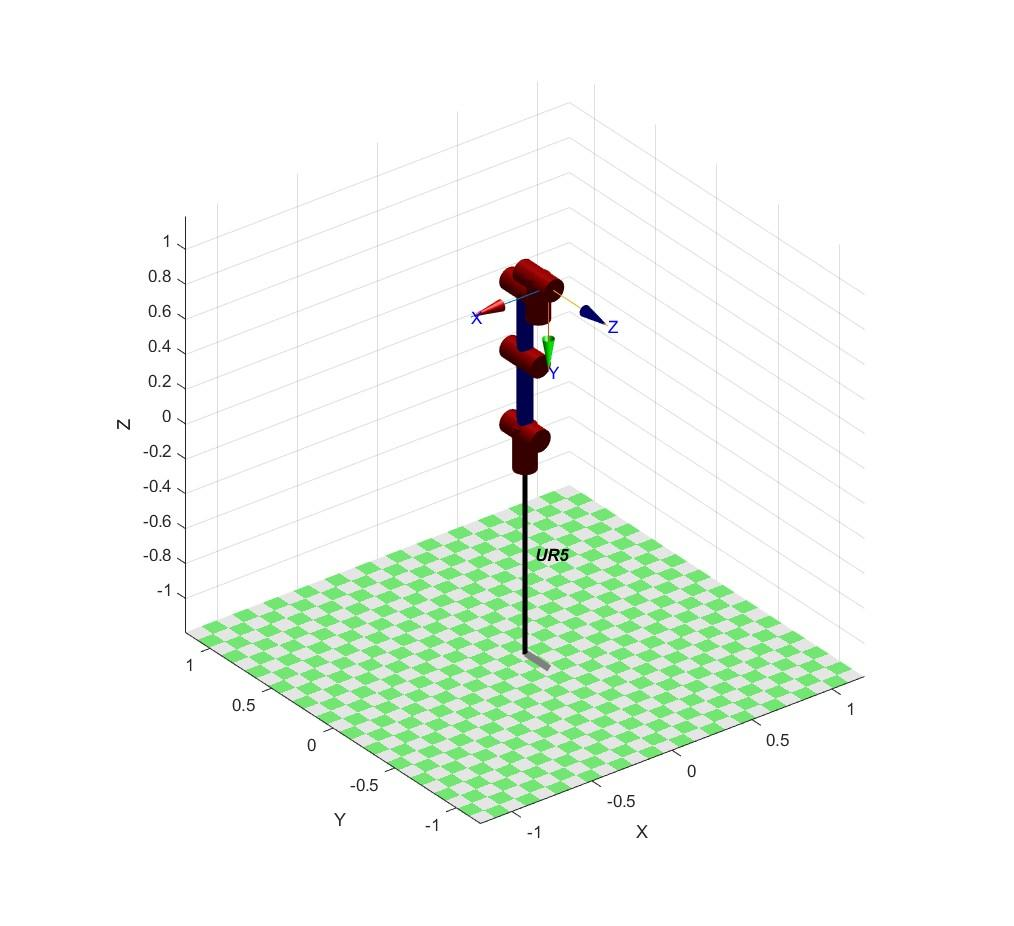

## 2. Symbolic Toolbox

On this part of the projecte, the robot Kinematics would be computed. To do so, the Jacobians would be determined, and both the Forward and Inverse Kinematics would be computed.

### 2.a. Compute Forward Kinematics

The FK will be computed using the DH parameters previously determined. To code the FK with the Symbolic Toolbox, first it is necessary to define all the variables that are used on the formulas.

% joint variables
syms qi
syms q1
syms q2
syms q3
syms q4
syms q5
syms q6
assume(qi,'real')
assume(q1,'real')
assume(q2,'real')
assume(q3,'real')
assume(q4,'real')
assume(q5,'real')
assume(q6,'real')

% link lengths
syms ai
syms a1
syms a2
syms a3
syms a4
syms a5
syms a6
assume(ai,'real')
assume(a1,'real')
assume(a2,'real')
assume(a3,'real')
assume(a4,'real')
assume(a5,'real')
assume(a6,'real')

% link offsets
syms di
syms d1
syms d2
syms d3
syms d4
syms d5
syms d6
assume(di,'real')
assume(d1,'real')
assume(d2,'real')
assume(d3,'real')
assume(d4,'real')
assume(d5,'real')
assume(d6,'real')

% link twists
syms alphai
syms alpha1
syms alpha2
syms alpha3
syms alpha4
syms alpha5
syms alpha6
assume(alphai,'real')
assume(alpha1,'real')
assume(alpha2,'real')
assume(alpha3,'real')
assume(alpha4,'real')
assume(alpha5,'real')
assume(alpha6,'real')

% joint offsets
syms offseti
syms offset1
syms offset2
syms offset3
syms offset4
syms offset5
syms offset6
assume(offseti,'real')
assume(offset1,'real')
assume(offset2,'real')
assume(offset3,'real')
assume(offset4,'real')
assume(offset5,'real')
assume(offset6,'real')

After that, the A matrices between joints can be computed. The general formula used is the following:

% Generic formula using DH parameters
A01i = [cos(qi+offseti) -sin(qi+offseti)*cos(alphai)  sin(qi+offseti)*sin(alphai) ai*cos(qi+offseti);...
       sin(qi+offseti)  cos(qi+offseti)*cos(alphai) -cos(qi+offseti)*sin(alphai) ai*sin(qi+offseti);...
          0     sin(alphai)          cos(alphai)         di;...
          0    0     0    1]

$$A01i = \left(\begin{array}{cccc} \cos\left(\mathrm{offseti}+\mathrm{qi}\right) & -\sin\left(\mathrm{offseti}+\mathrm{qi}\right)\,\cos\left(\mathrm{alphai}\right) & \sin\left(\mathrm{offseti}+\mathrm{qi}\right)\,\sin\left(\mathrm{alphai}\right) & \mathrm{ai}\,\cos\left(\mathrm{offseti}+\mathrm{qi}\right)\\ \sin\left(\mathrm{offseti}+\mathrm{qi}\right) & \cos\left(\mathrm{offseti}+\mathrm{qi}\right)\,\cos\left(\mathrm{alphai}\right) & -\cos\left(\mathrm{offseti}+\mathrm{qi}\right)\,\sin\left(\mathrm{alphai}\right) & \mathrm{ai}\,\sin\left(\mathrm{offseti}+\mathrm{qi}\right)\\ 0 & \sin\left(\mathrm{alphai}\right) & \cos\left(\mathrm{alphai}\right) & \mathrm{di}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

To compute the matrices for each pair of consecutive joints, the values of the DH parameters must be specified. Only the theta parameter is needed because the others have been already determined. It has been considered the robot in the home configuration, so all the offsets are set to zero.

% theta
vtheta1 = 0;
vtheta2 = 0; % -pi/2
vtheta3 = 0;
vtheta4 = 0; % -pi/2
vtheta5 = 0;
vtheta6 = 0;

% A matrices (numerical expression)
A01 = subs(A01i,{ai,di,alphai,offseti,qi},{ va1,   vd1,  valpha1, vtheta1,  q1});
A12 = subs(A01i,{ai,di,alphai,offseti,qi},{ va2,   vd2,  valpha2, vtheta2,  q2});
A23 = subs(A01i,{ai,di,alphai,offseti,qi},{ va3,   vd3,  valpha3, vtheta3,  q3});
A34 = subs(A01i,{ai,di,alphai,offseti,qi},{ va4,   vd4,  valpha4, vtheta4,  q4});
A45 = subs(A01i,{ai,di,alphai,offseti,qi},{ va5,   vd5,  valpha5, vtheta5,  q5});
A56 = subs(A01i,{ai,di,alphai,offseti,qi},{ va6,   vd6,  valpha6, vtheta6,  q6});

Finally, the Forward Kinematics is computed.

% Forward Kinematics
A06 = simplify(A01*A12*A23*A34*A45*A56)

With this huge dimension of the formulas obtained, it is better to define some position, and compute the FK for this configuration.

qa = [pi/4,pi/3,pi/2,pi/4,pi/3,pi/2];
T06 = round(subs(A06,{q1,q2,q3,q4,q5,q6},{qa}),4)

$$T06 = \left(\begin{array}{cccc} 0.183 & -0.2709 & 0.9451 & 0.2276\\ 0.183 & 0.9539 & 0.238 & 0.015\\ -0.9659 & 0.1294 & 0.2241 & -0.3651\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

### 2.b. Compute Geometric and Analytic Jacobians

With the previously calculated transformation matrices it is possible to compute both Geometric and Analytic Jacobian.

#### Geometric Jacobian

To obtain the Geometric Jacobian, first, the origin of each link reference frame is represented in the base frame:

% Origin of reference frames w.r.t. base frame
p0 = [0 0 0 1]';
p1 = A01*p0;
p2 = A01*A12*p0;
p3 = A01*A12*A23*p0;
p4 = A01*A12*A23*A34*p0;
p5 = A01*A12*A23*A34*A45*p0;
p6 = A01*A12*A23*A34*A45*A56*p0;

Then, the z-axes of the link reference frames are computed:

% z-axes of reference frames w.r.t. base frame
z0 = [0 0 1]';
z1 = A01(1:3,1:3)*z0;
z2 = A01(1:3,1:3)*A12(1:3,1:3)*z0;
z3 = A01(1:3,1:3)*A12(1:3,1:3)*A23(1:3,1:3)*z0;
z4 = A01(1:3,1:3)*A12(1:3,1:3)*A23(1:3,1:3)*A34(1:3,1:3)*z0;
z5 = A01(1:3,1:3)*A12(1:3,1:3)*A23(1:3,1:3)*A34(1:3,1:3)*A45(1:3,1:3)*z0;

Finally, the Geometric Jacobian is:

J = [ cross(z0,p6(1:3)-p0(1:3)),  cross(z1,p6(1:3)-p1(1:3)),  cross(z2,p6(1:3)-p2(1:3)), cross(z3,p6(1:3)-p3(1:3)), cross(z4,p6(1:3)-p4(1:3)), cross(z5,p6(1:3)-p5(1:3)),;...
               z0                          z1                          z2                         z3                         z4                         z5];
J = simplify(J)

To obtain a numerical expression of the Jacobian, an specific configuration is used.

qa = [pi/4,pi/3,pi/2,pi/4,pi/3,pi/2];
vJ = round(subs(J, {q1,q2,q3,q4,q5,q6}, {qa}),3)

$$vJ = \left(\begin{array}{cccccc} -0.015 & 0.321 & 0.061 & -0.078 & -0.022 & 0\\ 0.228 & 0.321 & 0.061 & -0.078 & 0.079 & 0\\ 0 & 0.172 & 0.384 & 0.044 & 0.011 & 0\\ 0 & 0.707 & 0.707 & 0.707 & -0.183 & 0.945\\ 0 & -0.707 & -0.707 & -0.707 & -0.183 & 0.238\\ 1.0 & 0 & 0 & 0 & 0.966 & 0.224 \end{array}\right)$$

#### Analytic Jacobian

Now, the Analytic Jacobian will be computed. For this one, the A matrices calculated before will be used too.

First, the linear part of the Analytic Jacobian is determined:

% End effector position
Pe = A06(:,4);

% Linear part computation
dPexdq1 = diff(Pe(1),q1);
dPexdq2 = diff(Pe(1),q2);
dPexdq3 = diff(Pe(1),q3);
dPexdq4 = diff(Pe(1),q4);
dPexdq5 = diff(Pe(1),q5);
dPexdq6 = diff(Pe(1),q6);
dPeydq1 = diff(Pe(2),q1);
dPeydq2 = diff(Pe(2),q2);
dPeydq3 = diff(Pe(2),q3);
dPeydq4 = diff(Pe(2),q4);
dPeydq5 = diff(Pe(2),q5);
dPeydq6 = diff(Pe(2),q6);
dPezdq1 = diff(Pe(3),q1);
dPezdq2 = diff(Pe(3),q2);
dPezdq3 = diff(Pe(3),q3);
dPezdq4 = diff(Pe(3),q4);
dPezdq5 = diff(Pe(3),q5);
dPezdq6 = diff(Pe(3),q6);

% Analytic Jacobian linear part
Jp = [dPexdq1 dPexdq2 dPexdq3 dPexdq4 dPexdq5 dPexdq6;...
      dPeydq1 dPeydq2 dPeydq3 dPeydq4 dPeydq5 dPeydq6;...
      dPezdq1 dPezdq2 dPezdq3 dPezdq4 dPezdq5 dPezdq6];
Jp = simplify(Jp);

Then, the angular part of the Analytic Jacobian is determined.

% End effector orientation
Phie = A06(1:3,1:3);

% ZYZ Euler angles
phi = atan2(Phie(2,3),Phie(1,3));
theta = atan2(sqrt(Phie(1,3)^2+Phie(2,3)^2),Phie(3,3));
psi = atan2(Phie(3,2),-Phie(3,1));

% Angular part computation
dphidq1 = diff(phi,q1);
dphidq2 = diff(phi,q2);
dphidq3 = diff(phi,q3);
dphidq4 = diff(phi,q4);
dphidq5 = diff(phi,q5);
dphidq6 = diff(phi,q6);
dthetadq1 = diff(theta,q1);
dthetadq2 = diff(theta,q2);
dthetadq3 = diff(theta,q3);
dthetadq4 = diff(theta,q4);
dthetadq5 = diff(theta,q5);
dthetadq6 = diff(theta,q6);
dpsidq1 = diff(psi,q1);
dpsidq2 = diff(psi,q2);
dpsidq3 = diff(psi,q3);
dpsidq4 = diff(psi,q4);
dpsidq5 = diff(psi,q5);
dpsidq6 = diff(psi,q6);

% Analytic Jacobian linear part
JPhi = [dphidq1 dphidq2 dphidq3 dphidq4 dphidq5 dphidq6;...
      dthetadq1 dthetadq2 dthetadq3 dthetadq4 dthetadq5 dthetadq6;...
      dpsidq1 dpsidq2 dpsidq3 dpsidq4 dpsidq5 dpsidq6];
JPhi = simplify(JPhi);

Finally, the Analytic Jacobian is:

JA = [Jp;JPhi];

To obtain a numerical expression of the Jacobian, an specific configuration is used.

qa = [pi/4,pi/3,pi/2,pi/4,pi/3,pi/2];
vJA = round(subs(JA, {q1,q2,q3,q4,q5,q6}, {qa}),3)

$$vJA = \left(\begin{array}{cccccc} -0.015 & 0.321 & 0.061 & -0.078 & -0.022 & 0\\ 0.228 & 0.321 & 0.061 & -0.078 & 0.079 & 0\\ 0 & 0.172 & 0.384 & 0.044 & 0.011 & 0\\ 1.0 & -0.118 & -0.118 & -0.118 & 1.017 & 0\\ 0 & -0.858 & -0.858 & -0.858 & -0.133 & 0\\ 0 & 0.526 & 0.526 & 0.526 & -0.228 & 1.0 \end{array}\right)$$

#### Verification

In order to verify the correctness of the Analytic Jacobian, it will be compared to the Geometric Jacobian by the following expressions:

TA = vJ*inv(vJA);
T = round(TA(4:6,4:6),3)

$$T = \left(\begin{array}{ccc} 0 & -0.245 & 0.945\\ 0 & 0.97 & 0.238\\ 1.0 & 0 & 0.224 \end{array}\right)$$

% Angular part of Analytic Jacobian
JA_ang = vJA(4:6,:)

$$JA\_ang = \left(\begin{array}{cccccc} 1.0 & -0.118 & -0.118 & -0.118 & 1.017 & 0\\ 0 & -0.858 & -0.858 & -0.858 & -0.133 & 0\\ 0 & 0.526 & 0.526 & 0.526 & -0.228 & 1.0 \end{array}\right)$$

J_ang2 = round(T*JA_ang,3)

$$J\_ang2 = \left(\begin{array}{cccccc} 0 & 0.707 & 0.707 & 0.707 & -0.183 & 0.945\\ 0 & -0.707 & -0.707 & -0.707 & -0.183 & 0.238\\ 1.0 & 0 & 0 & 0 & 0.966 & 0.224 \end{array}\right)$$

% Angular part of Geometric Jacobian
J_ang = vJ(4:6,:)

$$J\_ang = \left(\begin{array}{cccccc} 0 & 0.707 & 0.707 & 0.707 & -0.183 & 0.945\\ 0 & -0.707 & -0.707 & -0.707 & -0.183 & 0.238\\ 1.0 & 0 & 0 & 0 & 0.966 & 0.224 \end{array}\right)$$

### 2.c. Compute Inverse Kinematics (iterative form)

The IK enables to find the joint values such that the end effector is at a desired position and orientation. The iterative form consists on computing the joint values (q) continuously and making the error tend to zero. There are two different algorithms that can be implemented for this robot, but the Jacobian transpose will be used. The algorithm can be illustrated as the following control scheme:

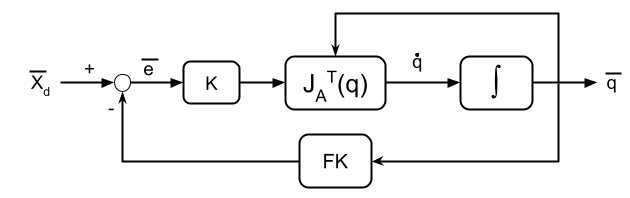

To implement this algorithm, a loop will be done till the desired position is the actual one (there is a threshold error to make the loop stop when the solution is sufficiently accurate). To make sure the desired position is a reachable one, the FK is used to convert certain joint values to a position and orientation. The angle-axis representation has been used to compute the orientation.

% Desired EE position and orientation
qd = [0 -pi/8 -pi/10 -pi/6 pi/12 pi/8];
T06d = double(subs(A06,{q1,q2,q3,q4,q5,q6},{qd}));
[angle,vect] = tr2angvec(T06d);
xd = [transl(T06d)',vect*sin(angle)]'

xd =    -0.7873
   -0.1887
    0.4951
    0.8114
    0.3135
   -0.4933


% Error threshold
et = 0.01;

% Gain & Time interval
K = 1.2;
Dt = 0.01;

% Actual position and orientation (considering q0) - revisar offsets!! o canvir posicio inicial
q0 = [0 0 0 0 0 0]';
q0(q0 == 0) = eps;      % if this is not done, the JA computation produces an error (division by 0)
qc = q0;
T06c = double(subs(A06,{q1,q2,q3,q4,q5,q6},{qc'}));
[angle,vect] = tr2angvec(T06c);
xc = [transl(T06c);vect'*sin(angle)];

% Initial error
error = xd-xc;

% Variables to enable the study of the iterative process
matriu = [];
matriu2 = [];
matriu3 = [];
iterac = [];

% Iterative process
iter = 1;
while (max(abs(error)) > et)
    % Inverse Kinematics
    JAc = double(subs(JA,{q1,q2,q3,q4,q5,q6},{qc'}));
    qdot = JAc'*(error*K);
    qc = qc + (qdot/norm(qdot))*Dt;
    % Forward Kinematics
    T06c = double(subs(A06,{q1,q2,q3,q4,q5,q6},{qc'}));
    [angle,vect] = tr2angvec(T06c);
    xc = [transl(T06c);vect'*sin(angle)];
    % New error
    error = xd-xc;
    iter = iter + 1;
    % Actualize study variables
    matriu = [matriu xc];
    matriu2 = [matriu2 qc];
    matriu3 = [matriu3 error];
    iterac = [iterac iter];
end

After 223 iterations, the robot has arrived to the position:

xc

xc =    -0.7774
   -0.1920
    0.4879
    0.8094
    0.3137
   -0.4923


As it can be observed, both position and orientation are really similar to the desired ones.

It is possible to see how the position, joint values and the error have evolved during the process. In the next images there are represented the obtained values of those parameters along the movement.

#### Position and orientation (xc)

#### Joint values (qc)

#### Error

### 2.d. Compute Inverse Kinematics (closed form)

To compute a closed form solution of the IK an algebraic or geometric solution of the robot must be followed. First, it is necessary to have an homogeneous transofrmation matrix, because all the parameters used to obtain the joint values will be extracted from this matrix.

qa = [pi/4,pi/3,pi/2,pi/4,pi/3,pi/2];
T06 = double(subs(A06,{q1,q2,q3,q4,q5,q6},{qa}))

T06 =     0.1830   -0.2709    0.9451    0.2276
    0.1830    0.9539    0.2380    0.0150
   -0.9659    0.1294    0.2241   -0.3651
         0         0         0    1.0000


% Previous determinations
px = T06(1,4);
py = T06(2,4);
pz = T06(3,4);
r11 = T06(1,1); r12 = T06(1,2); r13 = T06(1,3);
r21 = T06(2,1); r22 = T06(2,2); r23 = T06(2,3);
r31 = T06(3,1); r32 = T06(3,2); r33 = T06(3,3);

It is important to higlight that in this resolution there are different solutions regarding to the sign of some variables. For this robot, the joint values that can have different values due to the sign of the angles used to compute them are q1, q3 and q5. This possibility to change the sign it is indicated on the code by *+- (term number)* at the end of the corresponding calculation.

% theta 1
ikA = py-vd6*r23;
ikB = px-vd6*r13;
ikq1 = atan2(sqrt(ikB^2+(-ikA)^2-vd4^2),vd4)+atan2(ikB,-ikA); % +- (1)
% theta 5
ikC = sin(ikq1)*r11-cos(ikq1)*r21;
ikD = cos(ikq1)*r22-sin(ikq1)*r12;
ikq5 = atan2(sqrt(ikC^2+ikD^2),sin(ikq1)*r13-cos(ikq1)*r23); % +-
% theta 6
ikq6 = atan2(ikD/sin(ikq5),ikC/sin(ikq5));
% theta 3
ikE = cos(ikq1)*r11+sin(ikq1)*r21;
ikF = cos(ikq5)*cos(ikq6);
ikqaux = atan2(r31*ikF-sin(ikq6)*ikE,ikF*ikE+sin(ikq6)*r31);
ikPC = cos(ikq1)*px+sin(ikq1)*py-sin(ikqaux)*vd5+cos(ikqaux)*sin(ikq5)*vd6;
ikPS = pz-vd1+cos(ikqaux)*vd5+sin(ikqaux)*sin(ikq5)*vd6;
ikq3 = atan2(sqrt(1-((ikPS^2+ikPC^2-va2^2-va3^2)/(2*va2*va3))^2),(ikPS^2+ikPC^2-va2^2-va3^2)/(2*va2*va3)); % +-
% theta 2
ikq2 = atan2(ikPS,ikPC)-atan2(sin(ikq3)*va3,cos(ikq3)*va3+va2);
% theta 4
ikq4 = ikqaux-ikq2-ikq3;

Finally, the joint values obtained are:

ikq = [ikq1 ikq2 ikq3 ikq4 ikq5 ikq6]

ikq =     2.2952    0.4186    2.1421   -3.0245    0.5247   -1.0290


As can be seen on the result, the joint values of qa and ikq are different. In order to verify that the robot has the end effector on the same position and orientation, it has been plotted.

First, when joint values are qa:

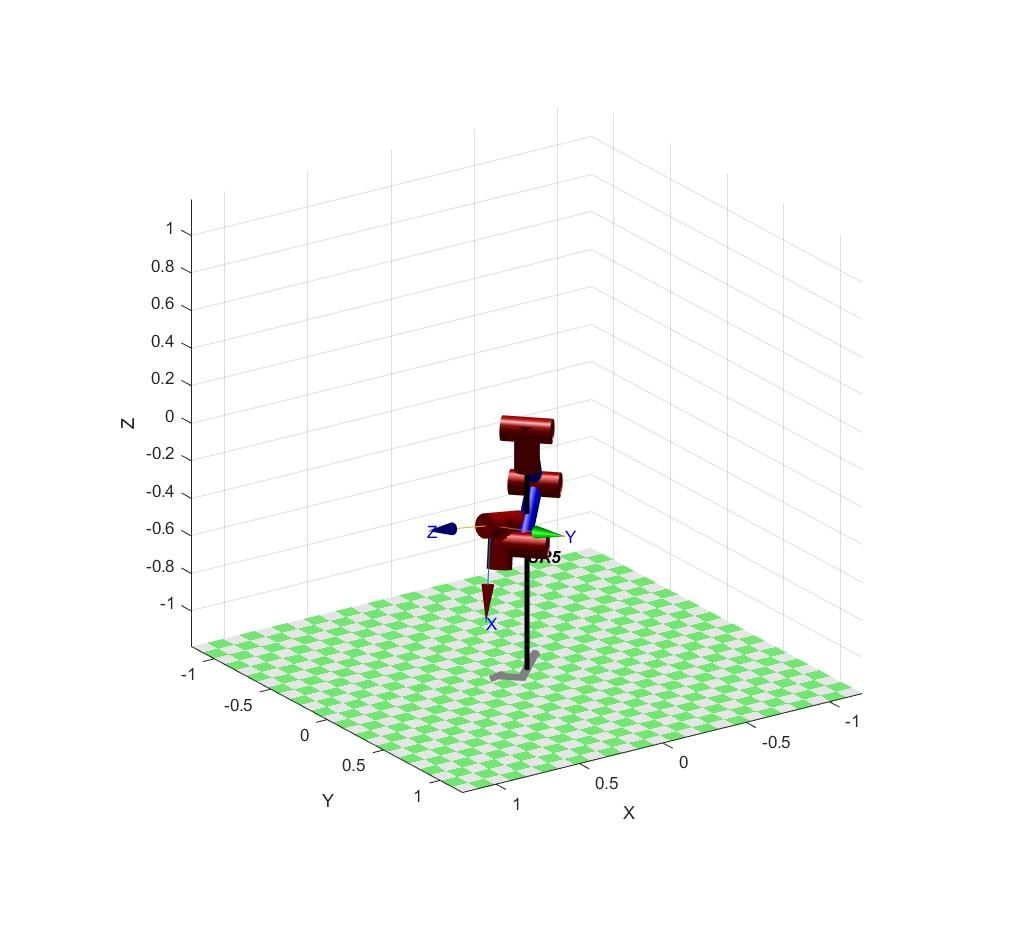

Then, when joint values are ikq: